clear; clc; close all;
rng(1)

## a


BER_20 = OFDM(20, true)

BER_20 = 0

## b

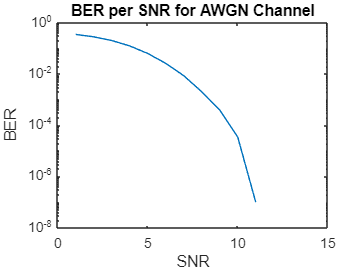


SNRs = 0 : 15;
BERs = zeros(size(SNRs));
for snr = SNRs
    BERs(snr+1) = OFDM(snr, false);
end
semilogy(BERs)
xlabel('SNR')
ylabel('BER')
title("BER per SNR for AWGN Channel")
xlim([0 15])

%% c

## d

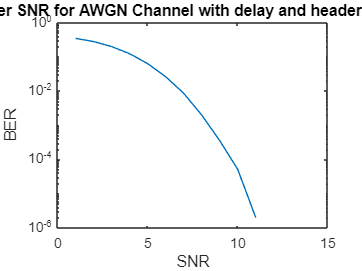


SNRs = 0 : 15;
BERs = zeros(size(SNRs));
for snr = SNRs
    BERs(snr+1) = OFDM(snr, true);
end
semilogy(BERs)
xlabel('SNR')
ylabel('BER')
title("BER per SNR for AWGN Channel with delay and header detecting")
xlim([0 15])

## Transmitter

function BER=OFDM(SNR, IsDelayed)
%% Generate random data
symbols_gray = [0 1 3 2];
M = 1e7;
x_bits = randi([0, 1], M, 1);
%% QPSK modulation
decimal_indices = bi2de(reshape(x_bits, 2, []).', 'left-msb');
x_symbols = symbols_gray(decimal_indices + 1).';


IFFT_length = 1024;
nc = 400;
sfc = ceil(2^13 / nc);
symbols_per_frame = nc * sfc;
number_of_frames = ceil(length(x_symbols) / symbols_per_frame);


zero_pad = zeros(number_of_frames*sfc*nc - length(x_symbols), 1);
x_symbols = [x_symbols; zero_pad];


%% frame devider & serial to parallel
symbol_matrix1 = reshape(x_symbols, sfc, nc, number_of_frames);

%% DPSK Modulation
reference_row = randi([0, 3], nc, number_of_frames);
reference_row_3D = reshape(reference_row, [1, size(reference_row)]);
symbol_matrix = [reference_row_3D; symbol_matrix1];

dpsk_matrix1 = zeros(size(symbol_matrix));
dpsk_matrix1(1,:) = symbol_matrix(1,:);
for i = 2:size(symbol_matrix, 1)
    dpsk_matrix1(i,:, :) = mod(symbol_matrix(i, :, :) + symbol_matrix(i-1, :, :), 4);
end
dpsk_matrix = exp(1j * pi/2 * dpsk_matrix1);

%% IFFT bins allocation
ifft_input = ifft_bins_allocation(IFFT_length, number_of_frames, nc, sfc, dpsk_matrix);
%% IFFT
ifft_output = ifft(ifft_input, IFFT_length, 2);
ofdm_frames = (ifft_output); % Keep only real part

%% CP addition
CP_length = round(0.25 * IFFT_length);
cp = ofdm_frames(:, end-CP_length+1:end, :);
ofdm_frames_with_CP = cat(2, cp, ofdm_frames);

%% parallel to serial
serial_ofdm = reshape(ofdm_frames_with_CP, [], size(ofdm_frames_with_CP, 3));

%% concatinate
header_ration = 8;
header_bits = randi([0, 1], (sfc + 1) * IFFT_length * header_ration, 1); %zeros((sfc + 1) * IFFT_length * header_ration, 1);%
cascaded_ofdm = serial_ofdm(:);

if IsDelayed
    delay_bits = randi([0, 1], randi([1 1000]), 1);
    cascaded_frames = [delay_bits; header_bits; cascaded_ofdm; header_bits];
else
    cascaded_frames = [header_bits; cascaded_ofdm; header_bits];
end

## Channel

signal_power = mean(abs(cascaded_ofdm).^2);
noise_power = signal_power / (10^(SNR/10));
noise = sqrt(noise_power/2) * (randn(size(cascaded_frames)) + sqrt(noise_power/2) * 1j * randn(size(cascaded_frames)));

cascaded_frames_noisy = cascaded_frames + noise;

## Detector

%% frame detection
if IsDelayed
    [corr, lag] = xcorr(cascaded_frames_noisy, header_bits);
    corr = corr(lag>=0);
    [~, sorted_idx] = sort(abs(corr), 'descend');
    header_start = min(sorted_idx(1:2));
    frame_start = header_start + length(header_bits);
    frames_detected = cascaded_frames_noisy(frame_start : frame_start + length(cascaded_ofdm) - 1);
else
    header_length = (sfc+1) * IFFT_length * header_ration;  
    frames_detected = cascaded_frames_noisy(header_length + 1 : end - header_length);
end
frames_detected = reshape(frames_detected, [], number_of_frames);
%% serial to parallel
frames_parallel = reshape(frames_detected, (sfc + 1), [], number_of_frames);
%% drop cp
ofdm_frames_no_CP = frames_parallel(:, CP_length+1 : end, :);
%% fft
fft_output = fft(ofdm_frames_no_CP, IFFT_length, 2);
%% Extract Carriers from fft bins
data = fft_output(:, 75:74+nc, :);

%% DPSK demodulation
phase_received = mod(angle(data), 2*pi);
symbols = round(phase_received / (pi/2));
symbols = mod(symbols, 4);
demodulated_data = zeros(size(data, 1), size(data, 2), size(data, 3));
demodulated_data(1,:) = symbols(1,:);
for i = 2:size(symbols, 1)
    demodulated_data(i,:, :) = mod(symbols(i, :, :) - demodulated_data(i-1, :, :), 4);
end
demodulated_data = demodulated_data(2:end, :, :);

%% Parallel to Serial & Cascade Frames
x_symbols_serial = reshape(demodulated_data, [], 1);
x_symbols_original = x_symbols_serial(1:end-size(zero_pad));

%% QPSK Modulation
inverse_gray_map = [0 1 3 2];
recovered_decimal_indices = inverse_gray_map(x_symbols_original + 1);
recovered_bits_matrix = de2bi(recovered_decimal_indices, 2, 'left-msb');
x_bits_recovered = reshape(recovered_bits_matrix.', [], 1);
BER = sum(x_bits_recovered ~= x_bits, 'all') / numel(x_bits);
end


function ifft_input = ifft_bins_allocation(ifft_length, number_of_frames, nc, sfc, data)
    ifft_input = zeros(sfc+1, ifft_length, number_of_frames);
    ifft_input(:, 75:74+nc, :) = data;
    ifft_input(:, end-73-nc:end-74, :) = conj(data);
end